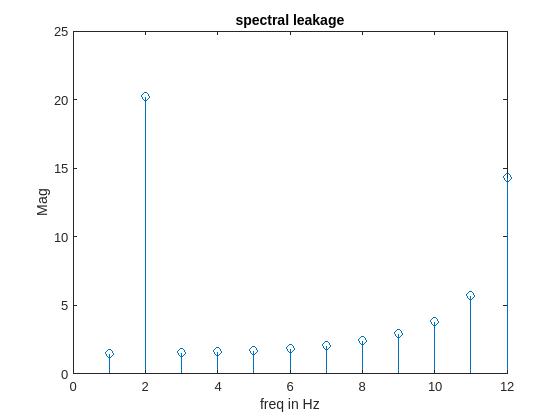

clc;clear;close all;
fm=input('Enter the frequency of the input signal');
fs=input('Enter the sampling frequency');
m=input('Enter the number of cycles of the input signal');

t=0.0001:1/fs:m/fm;
x=3*cos(2*pi*fm*t);
N=(m*fs/fm);
for k=1:N
 X1(k)=0;
for n=1:length(x)
 X1(k)=X1(k)+x(n).*exp((-i).*2.*pi.*(n-1).*(k-1)/N);
end
end
k=0:N-1;
f=k*fs/N;
figure(1);stem(abs(X1));xlabel('freq in Hz');ylabel('Mag'),title('spectral leakage');

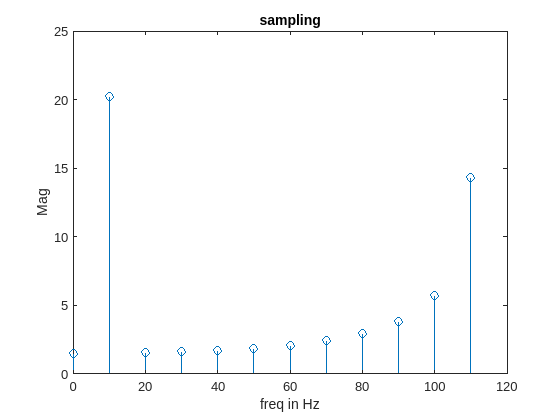

figure(2);stem(f,abs(X1));xlabel('freq in Hz');ylabel('Mag'),title('sampling');